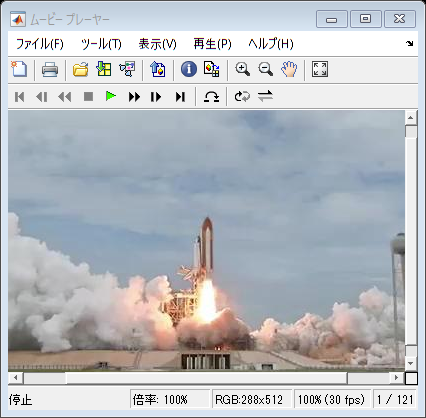

implay("shuttle.avi")

% implay("../../data/data/MathWorks Images/liquidVideo.mp4")

v = VideoReader("../../data/data/MathWorks Images/liquidVideo.mp4");
v.FrameRate

ans =     10



vOut = VideoWriter("liquidVideoBinary.mp4","MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut)
% j = 0;
for i = 1:v.NumFrames
    img = readFrame(v);
%     if (i == 92) || (i == 185) || (i == 224)
% %         str = ['frame_',num2str(i),' = img;'];
% %         eval(str)
%         j = j + 1;
%         imgs(:,:,:,j) = img;
%     end
    bw = segmentWater(img);
    frame = imfuse(img,bw,"montage");
    writeVideo(vOut,frame);

end
close(vOut)

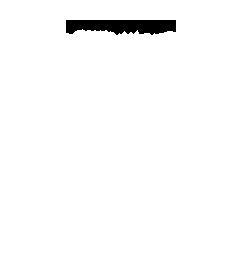

idx = 3;
img = imgs(:,:,:,idx);
bw = segmentWater(img);
imshow(bw)

function [BW,maskedRGBImage] = segmentWater(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 21-Feb-2023
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 1.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.477;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% default によるマスクのオープン
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
